# Lineární regresní model v kontextu RKHS

Držíme se **univerzální konstrukce lineárního RKHS modelu**.

Zvolíme množinu *X, *pracovat budeme s funkcemi na této množině.

clear
X = linspace(-0.5, 0.5, 100);
n = length(X); % délka regresorů

V tomto diskrétním případě tedy funkce na *X* jsou vektory délky *n*.

## Regrese podle vzorce (8.6b')

### Generátory

Libovolně, ale pevně vybereme vhodné nenulové generátory pro prostor HF konečné dimenze funkcí definovaných na *X*.

J = 51;           % počet generátorů
Phi = zeros(n, J); % generátory tvoří sloupce matice Phi
Phi(:, 1) = 1;
for j = 1:floor(J/2)
    Phi(:, 2*j)   = cos(2*pi*j*X);
    Phi(:, 2*j+1) = sin(2*pi*j*X);
end

Pro ilustraci je možné vykreslit libovolný z daných generátorů.

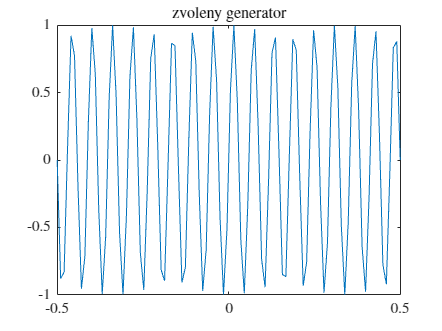

figure
plot(X, Phi(:, 35))
title('zvoleny generator')

Pro další použití budeme potřebovat všech *J* jádrových funkcí jednodimenzionálních RKHS prostorů příslušných jednotlivým generátorům, které proto uložíme.

jadra = cell(J, 1);
for j = 1:J
    jadra{j} = Phi(:, j)*Phi(:, j)';
end

Prostor HF = H(**K1**) je součtem jednodimenzionálních prostorů a jeho jádro je součtem jednotlivých jader.

K1 = zeros(n);
for j = 1:J
    K1 = K1 + jadra{j};
end

Zvolíme vhodnou podmnožinu generátorů pro model HL.

JL = 1:20; % indexy generátorů prostoru HL v původním systému Phi

Funkce, jejíž regresi budeme dělat, by měla náležet do prostoru HF, vytvoříme ji tudíž pomocí získaného jádra.

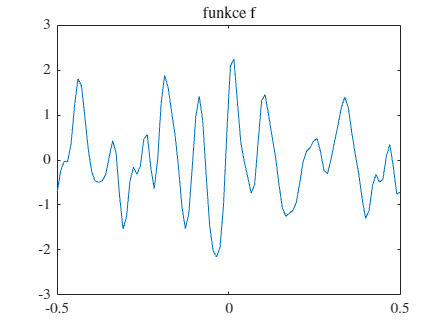

koeficienty = (rand(J, 1) < 0.2).*exp(-2*(1:J)'/J);
f = Phi*koeficienty;

% jak naše funkce vypadá?
figure
plot(X, f)
title('funkce f')

### Skalární součin v RKHS prostoru

Pro libovolné jádro budeme potřebovat skalární součin. Proto jej definujeme jako anonymní funkci tří proměnných (včetně jádra).

Pro výpočet skalárního součinu v RKHS prostoru s daným jádrem **K** využijeme výsledky v příkladu 8.56 (Vážený euklidovský prostor). Pro prvek **v** RKHS však potřebujeme znát takové koeficienty **b, **že **v** = **Kb**. Matice **K** však v tomto případě nemusí být regulární. Jednou z možností, jak získat vektor **b, **je pomoci si pseudoinverzí jádra.

soucin = @(u, v, jadro) u' * (pinv(jadro)*v)

soucin = function_handle with value:
    @(u,v,jadro)u'*(pinv(jadro)*v)


Podle Věty 8.18 (Mooreova–Aronszajnova) nezáleží a tom, jak určíme koeficienty **b**. V důkazu této věty je ukázáno, že skalární součin na RKHS prostoru je korektně zaveden, tzn. bez ohledu na volbu lineární kombinace **b** dostaneme součin **u** a **v** vždy stejný.

### Výpočet lineární regrese

Regresi počítáme dle výše použitého vzorce.

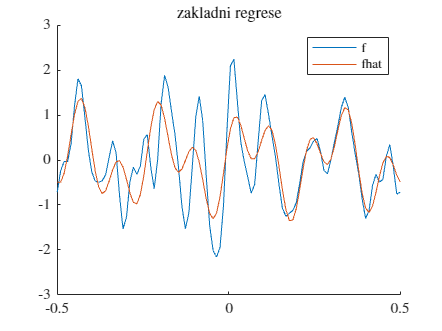

fhat_a = zeros(size(f));
for j = JL
    fhat_a = fhat_a + soucin(f, Phi(:, j), K1)*Phi(:, j);
end
figure
hold on
plot(X, f)
plot(X, fhat_a)
legend('f', 'fhat')
title('zakladni regrese')

## Vážená regrese

Vážíme jednotlivé generátory prostoru HF, zvolíme si tedy vektor vah délky *J*.

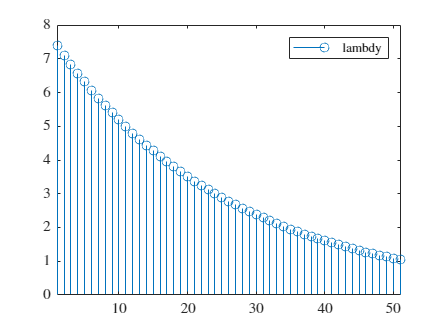

lambdy = exp(2*(J:-1:1)'/J);
figure
stem(lambdy)
xlim([1 J])
legend('lambdy')

Ověříme, že původní generátory mají (v příslušných jednodimenzionálních prostorech) normu 1/lambda.

normy = zeros(J, 1);
for j = 1:J
    normy(j) = sqrt(soucin(Phi(:, j), Phi(:, j), lambdy(j)^2*jadra{j}));
end
[normy, 1./lambdy] % zobrazíme porovnání

ans =     0.1353    0.1353
    0.1407    0.1407
    0.1464    0.1464
    0.1522    0.1522
    0.1583    0.1583
    0.1647    0.1647
    0.1712    0.1712
    0.1781    0.1781
    0.1852    0.1852
    0.1926    0.1926


Spočítáme regresi pro vážený případ, pro nějž však potřebujeme nové jádro **K2**. Výsledek porovnáme s neváženým případem.

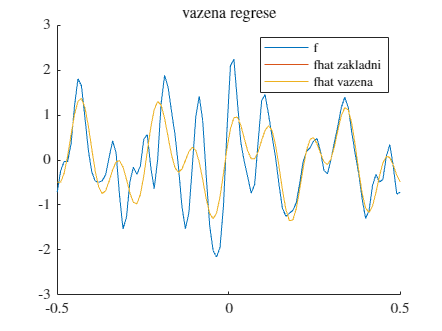

K2 = zeros(n);
for j = 1:J
    K2 = K2 + lambdy(j)^2*jadra{j};
end

% vzorec (8.6a') pro vážené regresory
fhat_vazena = zeros(size(f));
for j = JL
    fhat_vazena = fhat_vazena ...
        + soucin(f, lambdy(j)*Phi(:, j), K2)*lambdy(j)*Phi(:, j);
end

% vykreslení výsledku
figure
hold on
plot(X, f)
plot(X, fhat_a)
plot(X, fhat_vazena)
legend('f', 'fhat zakladni', 'fhat vazena')
title('vazena regrese')


% srovnání vážené a nevážené regrese
norm(fhat_vazena - fhat_a)

ans = 3.0290e-14

## Regrese podle vzorce (8.6b')

Předchozí výsledky chceme porovnat s alternativním přístupem, kdy RKHS prostor není přímo prostor funkcí, se kterými pracujeme, ale prostor parametrů. Tomuto prostoru budou opovídat operátory **T** (rekonstrukční) a **L** (diskretizační), přičemž v našem maticovém případě operátor **T** odpovídá matici, jejíž sloupce jsou zvolené regresory.

T = Phi(:, JL)

T =     1.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000
    1.0000   -0.9980   -0.0634    0.9920    0.1266   -0.9819   -0.1893    0.9679    0.2511   -0.9501   -0.3120    0.9284    0.3717   -0.9029   -0.4298    0.8738    0.4862   -0.8413   -0.5406    0.8053
    1.0000   -0.9920   -0.1266    0.9679    0.2511   -0.9284   -0.3717    0.8738    0.4862   -0.8053   -0.5929    0.7237    0.6901   -0.6306   -0.7761    0.5272    0.8497   -0.4154   -0.9096    0.2969
    1.0000   -0.9819   -0.1893    0.9284    0.3717   -0.8413   -0.5406    0.7237    0.6901   -0.5801   -0.8146    0.4154    0.9096   -0.2358   -0.9718    0.0476    0.9989    0.1423   -0.9898   -0.3271
    1.0000   -0.9679   -0.2511    0.8738    0.4862   -0.7237   -0.6901    0.5272    0.8497   -0.2969   -0.9549    0.0476    0.9989    0.2048   -0.9788   -0.4441    0.8960    0.6549   -0.7557  

L = T'

L =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -1.0000   -0.9980   -0.9920   -0.9819   -0.9679   -0.9501   -0.9284   -0.9029   -0.8738   -0.8413   -0.8053   -0.7660   -0.7237   -0.6785   -0.6306   -0.5801   -0.5272   -0.4723   -0.4154   -0.3569   -0.2969   -0.2358   -0.1736   -0.1108   -0.0476    0.0159    0.0792    0.1423    0.2048    0.2665    0.3271    0.3863    0.4441    0.5000    0.5539    0.6056    0.6549    0.7015    0.7453    0.7861    0.8237    0.8580    0.8888    0.9161    0.9397    0.9595    0.9754    0.9874    0.9955    0

Vyčíslíme jádro RKHS prostoru H(**K3**), což je prostor parametrů a jeho jádro odpovídá jádru **K*** v úvodu příkladu 8.64 (Lineární regresní model).

K3 = T'*T

K3 =   100.0000   -1.0000   -0.0000    1.0000   -0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000    0.0000    1.0000    0.0000   -1.0000    0.0000    1.0000    0.0000   -1.0000    0.0000    1.0000
   -1.0000   50.5000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000   -0.0000   -1.0000   -0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000
   -0.0000    0.0000   49.5000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    1.0000   -1.0000    0.0000   50.5000   -0.0000   -1.0000    0.0000    1.0000    0.0000   -1.0000    0.0000    1.0000    0.0000   -1.0000    0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000
   -0.0000   -0.0000    0.0000   -0.0000   49.5000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000 

Dle vzorce (8.6b') již můžeme snadno počítat regresi.

fhat_b = zeros(n, 1);
for i = 1:n
    fhat_b(i) = soucin(L*f, L(:, i), K3);
end

Výsledek vykreslíme a porovnáme s předchozím.

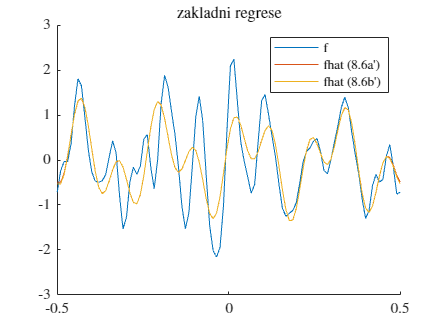

figure
hold on
plot(X, f)
plot(X, fhat_a)
plot(X, fhat_b)
legend('f', 'fhat (8.6a'')', 'fhat (8.6b'')')
title('zakladni regrese')


% srovnání regrese podle vzorce (8.6a') a podle vzorce (8.6b')
norm(fhat_a - fhat_b)

ans = 0.0939

### Proč zde dochází k odchylce výsledků?

V úvodu jsme vytvořili RKHS prostor H(**K1**) s využitím všech *J* generátorů. Regresorů je však méně, což skalární součin ve vzorci (8.6b') (prostor H(**K3**)) respektoval, ovšem ve vzorci (8.6a') (prostor H(**K1**)) nikoliv.

Shody dosáhneme, jestliže RKHS prostor funkcí na *X* potřebný pro vzorec (8.6a') vygenerujeme pouze našimi zvolenými regresory, místo H(**K1**) budeme počítat v novém prostoru H(**K4**).

% výpočet jádra
K4 = zeros(n);
for j = JL
    K4 = K4 + jadra{j};
end

% výpočet regrese
fhat_c = zeros(n, 1);
for j = JL
    fhat_c = fhat_c + soucin(f, Phi(:, j), K4)*Phi(:, j);
end

% srovnání regrese podle vzorce (8.6a') s upraveným součinem a podle vzorce (8.6b')
norm(fhat_c - fhat_b)

ans = 9.3393e-15

### Kontrola pomocí pseudoinverze

% výpočet regrese
fhat_d = T*pinv(T)*f;

% srovnání regrese pomocí pseudoinverze a podle vzorce (8.6b')
norm(fhat_d - fhat_b)

ans = 6.5851e-15